# Ecuatii neliniare


$$f\left(x\right)=0\Rightarrow x=?\;\textrm{radacina}\;\textrm{pentru}\;f\;\left(\textrm{fzero}-\textrm{ec}\ldotp \textrm{nelin},\textrm{fsolve}-\textrm{sist}\ldotp \textrm{ec}\ldotp \textrm{nelin}\right)$$


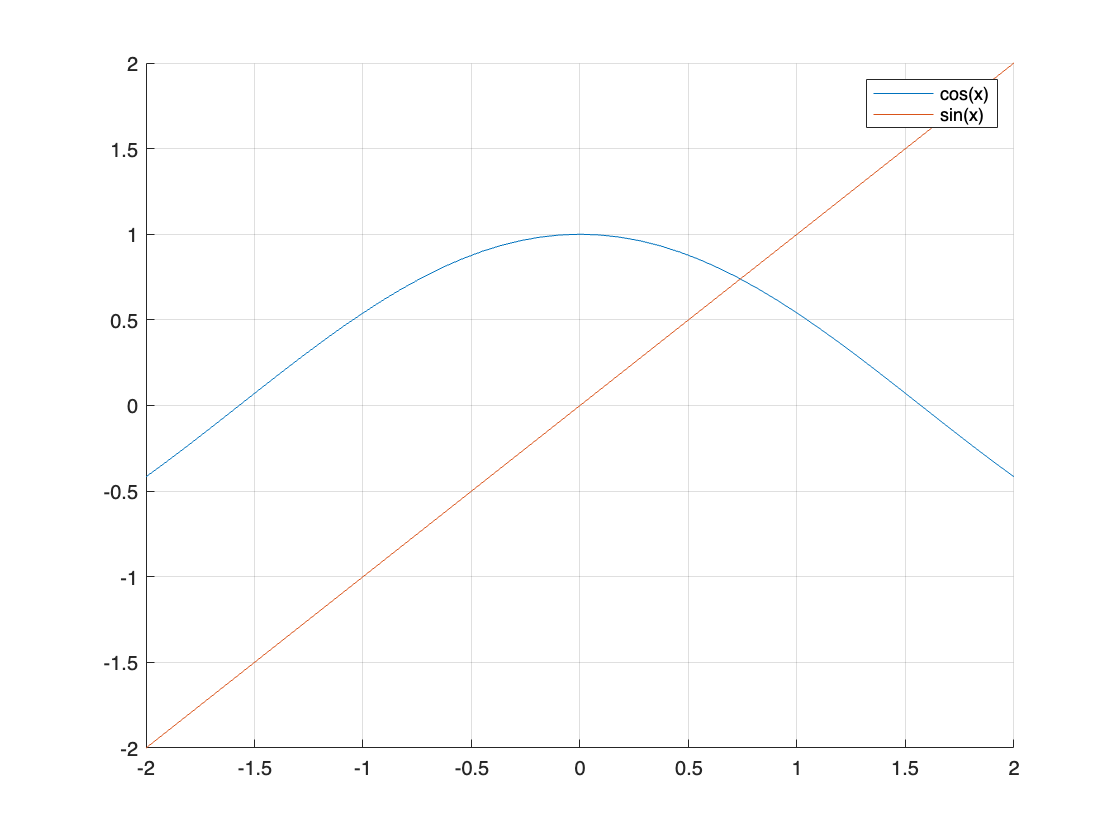

phi=@(x) cos(x);
f=@(x) x-phi(x);

clf; hold on; grid on;
fplot(@(x) phi(x), [-2 2])
fplot(@(x) x, [-2, 2])
legend("cos(x)", "sin(x)")

c0=fzero(f, pi/2)

c0 =          0.739085133215161


## Metoda bisectiunii

[c1,fc,nr_it]=bisection(f,0,pi/2)

c1 =          0.739085133215273


fc =       1.88848936488739e-13


nr_it =     40


## Metoda pozitiei false

[c2,fc,nr_it]=false_pos(f,0,pi/2)

c2 =          0.739085133215085


fc =      -1.26898491714655e-13


nr_it =     14


## Metoda secantei

[c3,fc,nr_it]=secant(f,0,pi/2)

c3 =          0.739085133215161


fc =      0


nr_it =      6


## Metoda Steffensen

[p,i]=Steffensen(phi,pi/4)

p =          0.739085133215161


i =      4


## Metoda Newton

df=@(x) 1+sin(x);
[c4,fc,nr_it]=Newton(f,df,pi/4)

c4 =          0.739085133215161


fc =       6.66133814775094e-16


nr_it =      3


## Metoda aproximatiilor succesive

[x1,nr_it]=succesiv(phi,pi/4), err=abs(c0-x1)

x1 =          0.739085133214831


nr_it =     65


err =       3.29736238313671e-13


phi2=@(x) x-f(x)./df(x1);
[x2,nr_it]=succesiv(phi2,pi/4), err=abs(c0-x2)

x2 =          0.739085133215161


nr_it =      4


err =      0
